## Step1. load the MCorrected data (motion correction and baseline correction) and continue preprocessing (filter_bandpass & smooth)

(only for individual trial: one animal in one experiment, EPM & 3-CEM & MEPM)

Preprocessing involve 4 steps: filter, smooth, motion correction, baseline correction

raw = readtimetable('data-000-MCorrected.csv','SampleRate',50);
%raw.camera_clock = raw.camera_clock*(10^(-9));
%optional, to make sure the fps is right~ the original setting is fps=50, that is, sampling rate=50Hz
raw.camera_clock = [];

注意：滤波这一项可以跳过，如果没有特定频率信号的污染，以及对比之后发现有明显的信号失真

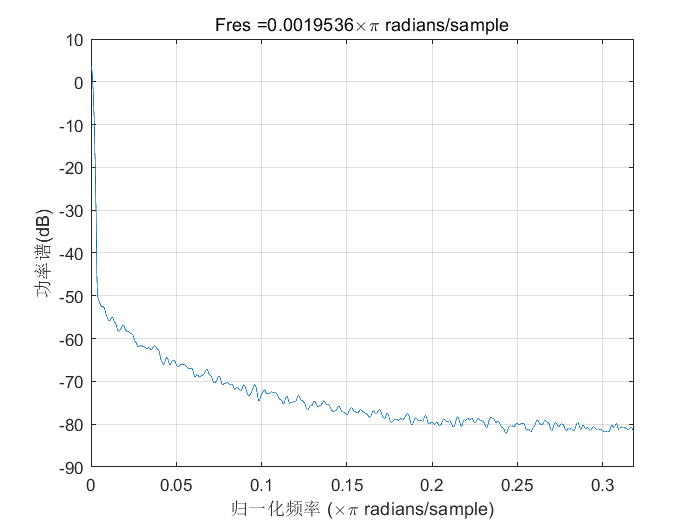

pspectrum(raw.channel_1,"power","FrequencyLimits",[0 1]);%show the power spectrum, determine the parameters of filter

Try different bandpass parameters (interesting to see the changes!)

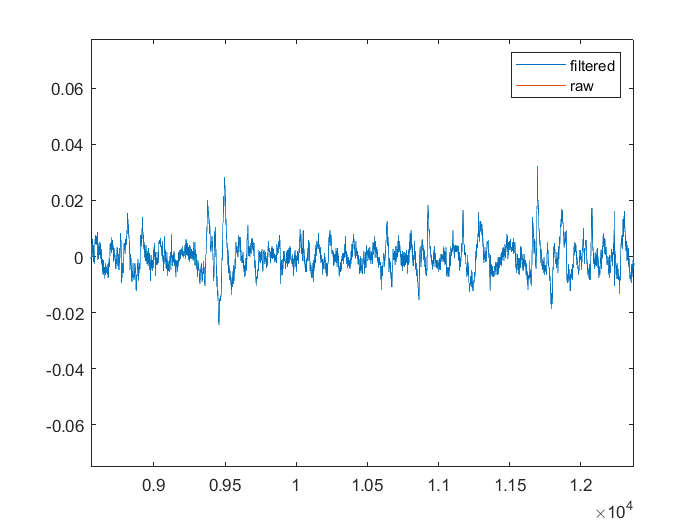

raw_filter = bandpass(raw.channel_1,[0.01,0.9]);
plot(raw_filter);
hold on
plot(raw.channel_1);
legend("filtered","raw");
hold off

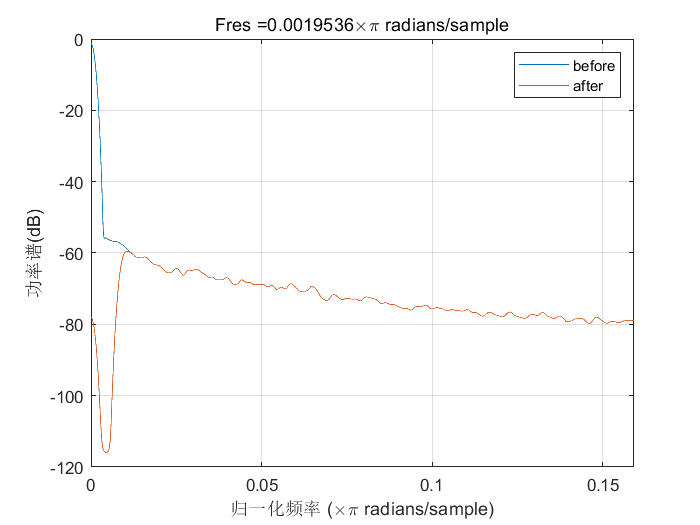

%compare the power spectrum of the data before and after process
pspectrum(raw.channel_1,"power","FrequencyLimits",[0 0.5]);
hold on
pspectrum(raw_filter,"power","FrequencyLimits",[0 0.5]);
legend("before","after")
hold off

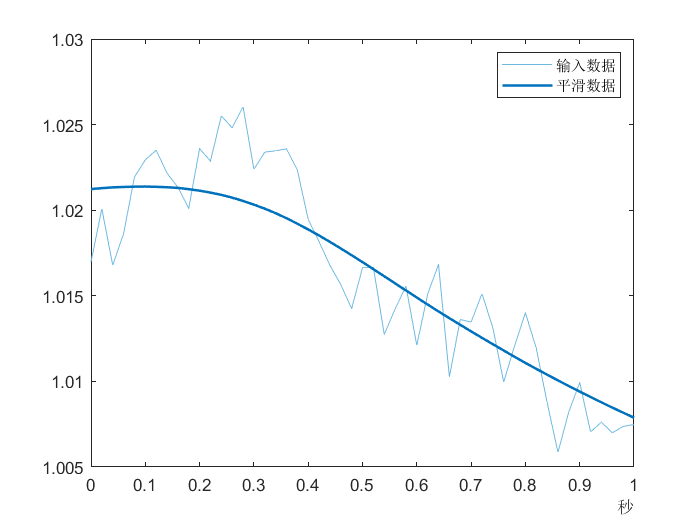

错误使用 xlim (line 31)
Limits 必须为包含递增的持续时间的 2 元素向量。

% 对输入数据进行平滑处理
raw_smooth = smoothdata(raw.channel_1,'gaussian',seconds(1.000014),...
    'SamplePoints',raw.Time);

% 显示结果
clf
plot(raw.Time,raw.channel_1,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(raw.Time,raw_smooth,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','平滑数据')
hold off
legend
xlim([10929 11175])

ylim([-0.00236 0.00081])

Try to smooth filtered data, by GUI; compare and find the best parameters and method:)

TIP: the parameters should be unified in all the trials

看情况，可以存处理后的信号在另一列，可比较前后的区别，在统计学上是否有差异

raw.channel_1 = raw_smooth;